clear
addpath('C:\Users\raque\OneDrive\Escritorio\UU\IP\project\Images')
images=struct('AX',zeros(1313,1750,5),'COR',zeros(1313,1750,5),'SAG',zeros(1313,1750,5));

for i=1:5
    filename="COR_"+i+".png";
    clear image;
    image = imread(filename);
    image = im2double(image);
    image = rgb2gray(image);
    images.COR(:,:,i)=image;
end

for i=1:5
    filename="AX_"+i+".png";
    clear image;
    image = imread(filename);
    image = im2double(image);
    image = rgb2gray(image);
    images.AX(:,:,i)=image;
end

for i=1:5
    filename="SAG_"+i+".png";
    clear image;
    image = imread(filename);
    image = im2double(image);
    image = rgb2gray(image);
    images.SAG(:,:,i)=image;
end

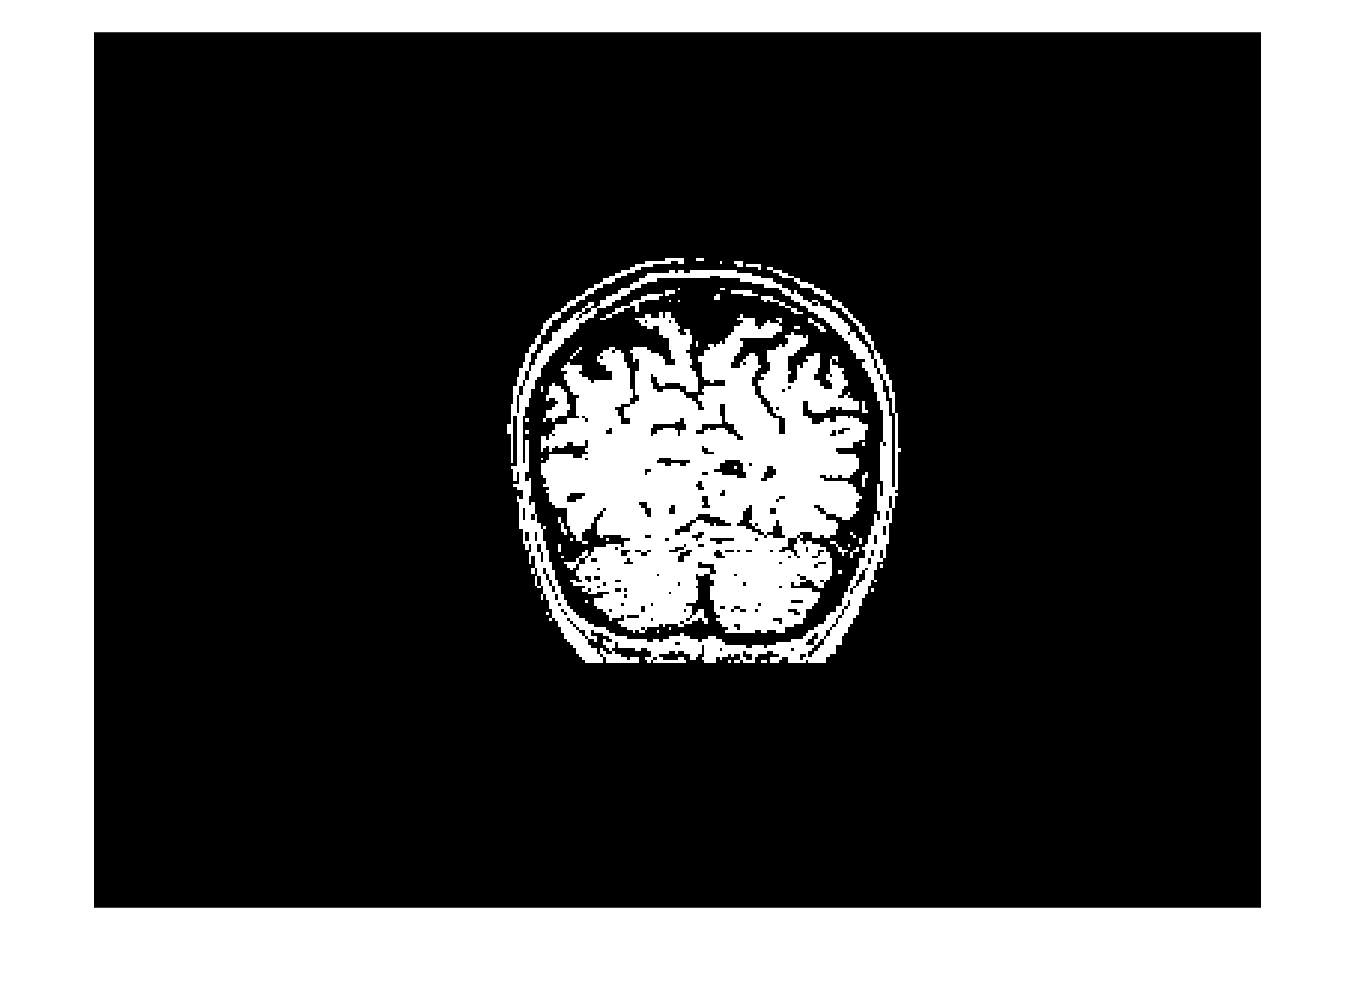

IM = images.COR(:,:,5);
Ta = graythresh(IM);
ta_image=IM<=Ta;  % Remove the values that are 0.
ta_image=~ta_image;
% ta_image = imbinarize(IM,Ta);
figure
imshow(ta_image)

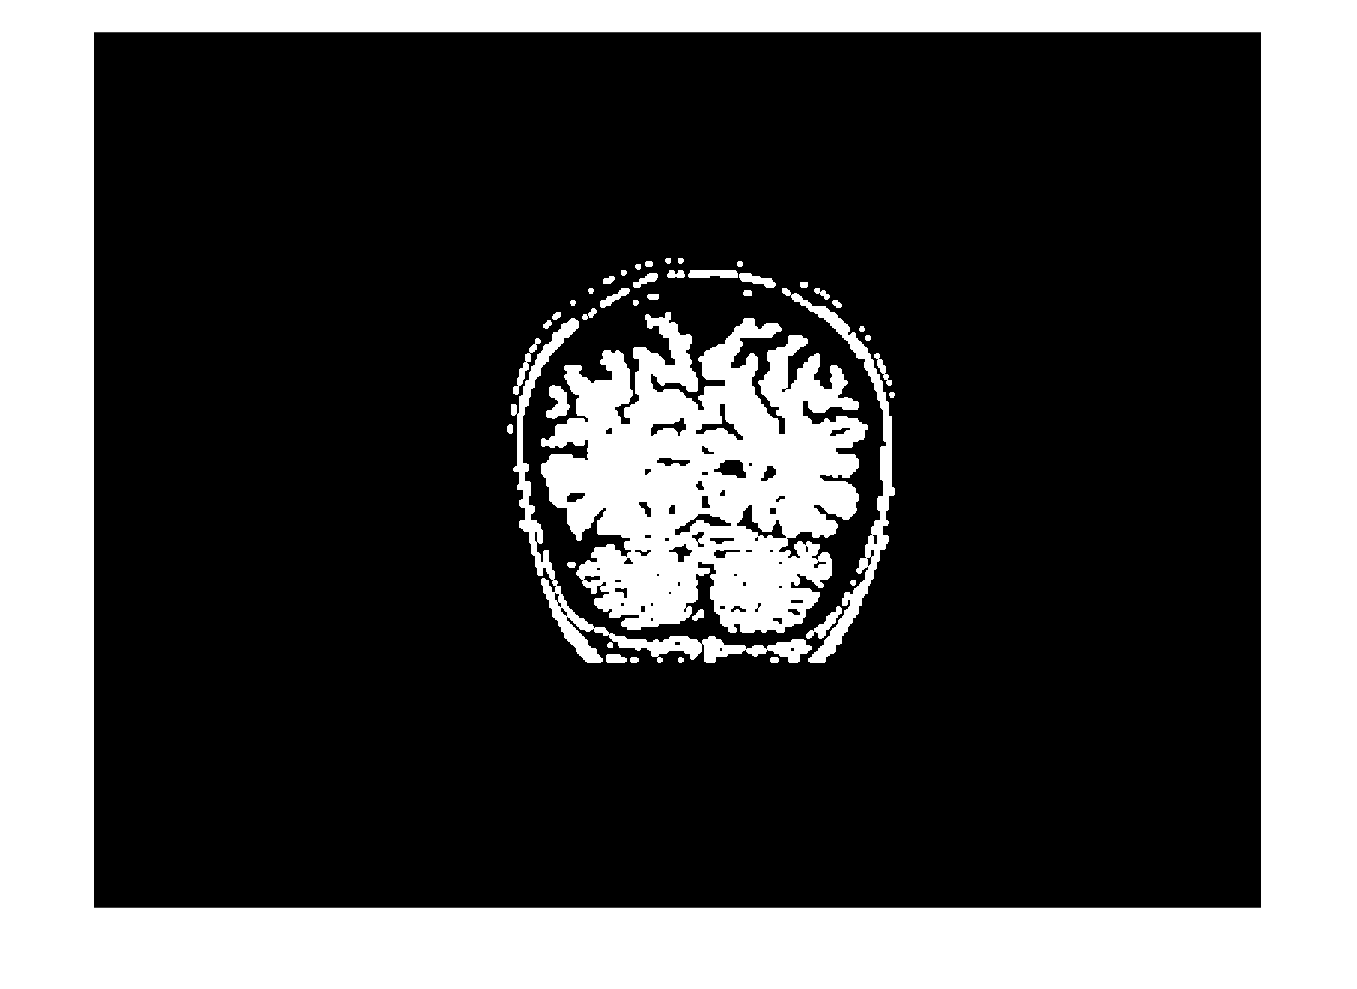


sea = strel('disk',5);
i1= imopen(ta_image,sea);
figure
imshow(i1)

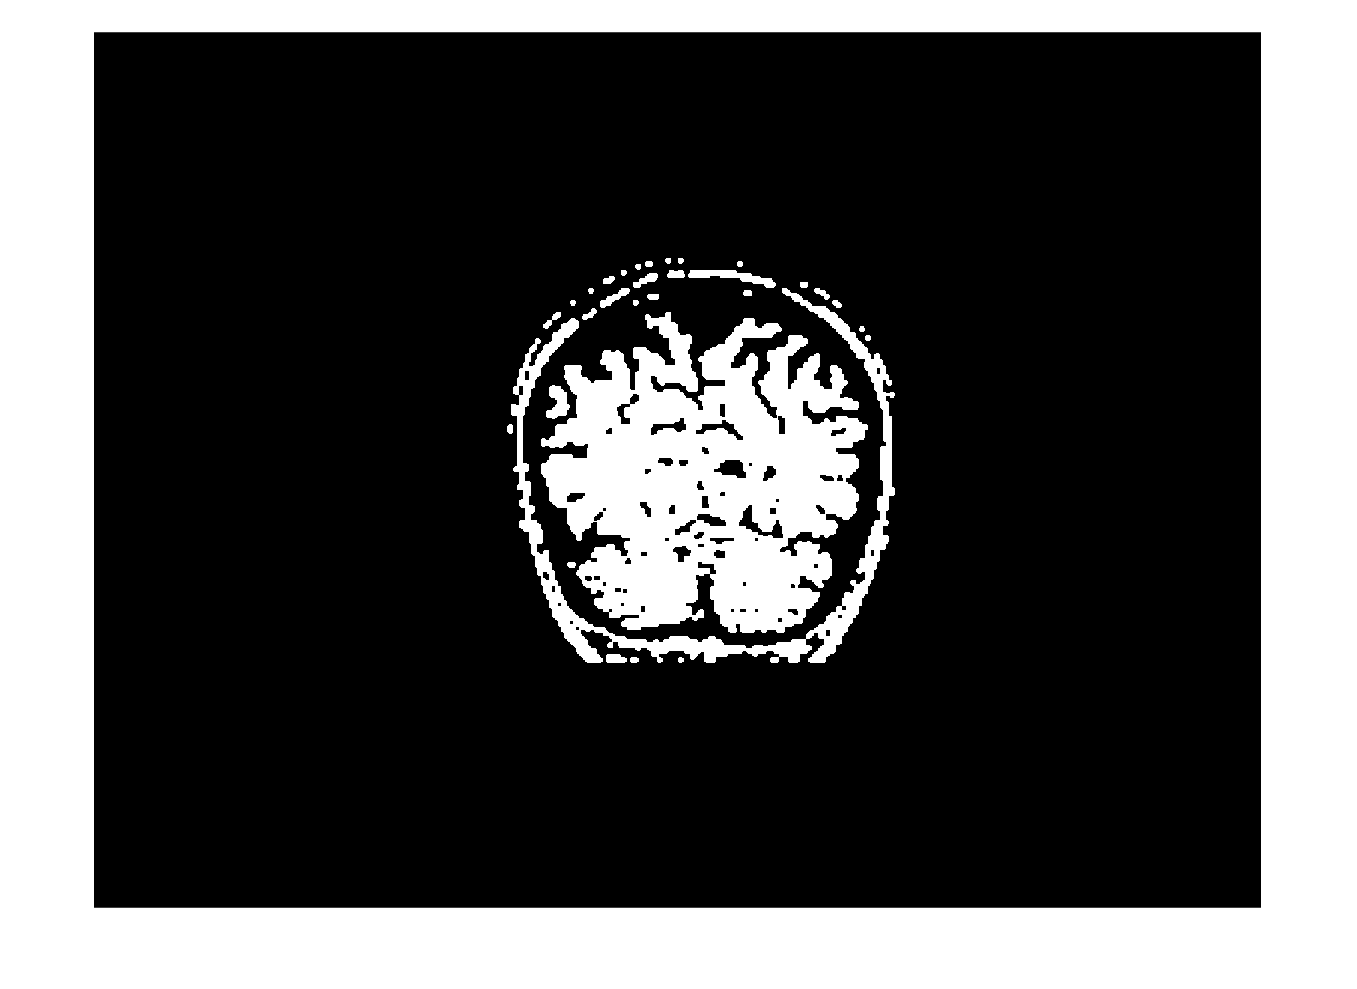


sec = strel('square',5);
i2 = imclose(i1,sec);
figure
imshow(i2,[])

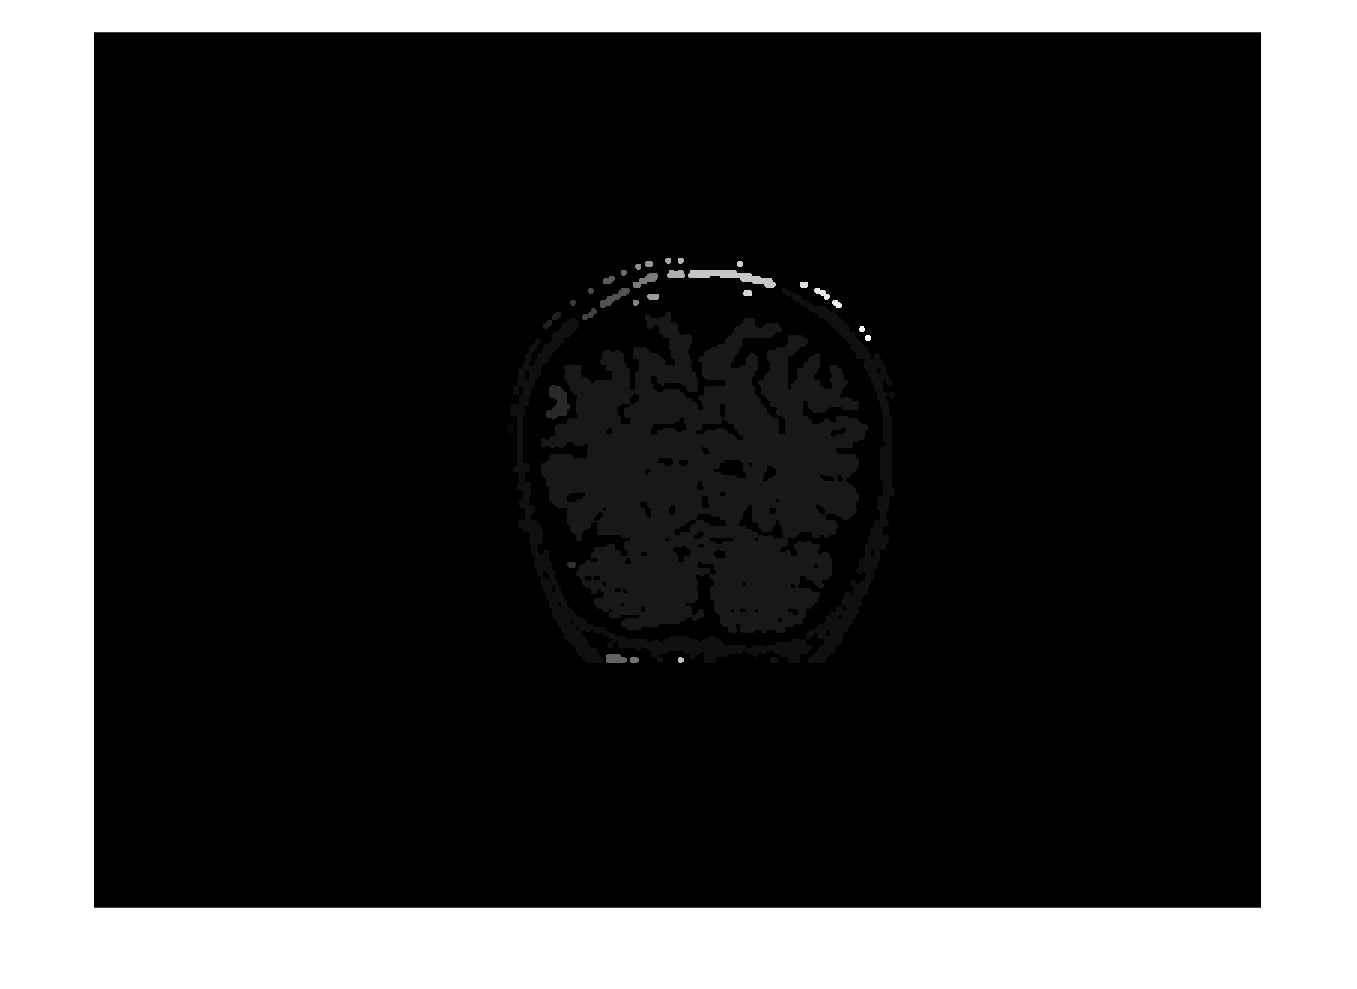


[L,N] = bwlabeln(i2,8);

figure
imshow(L,[])

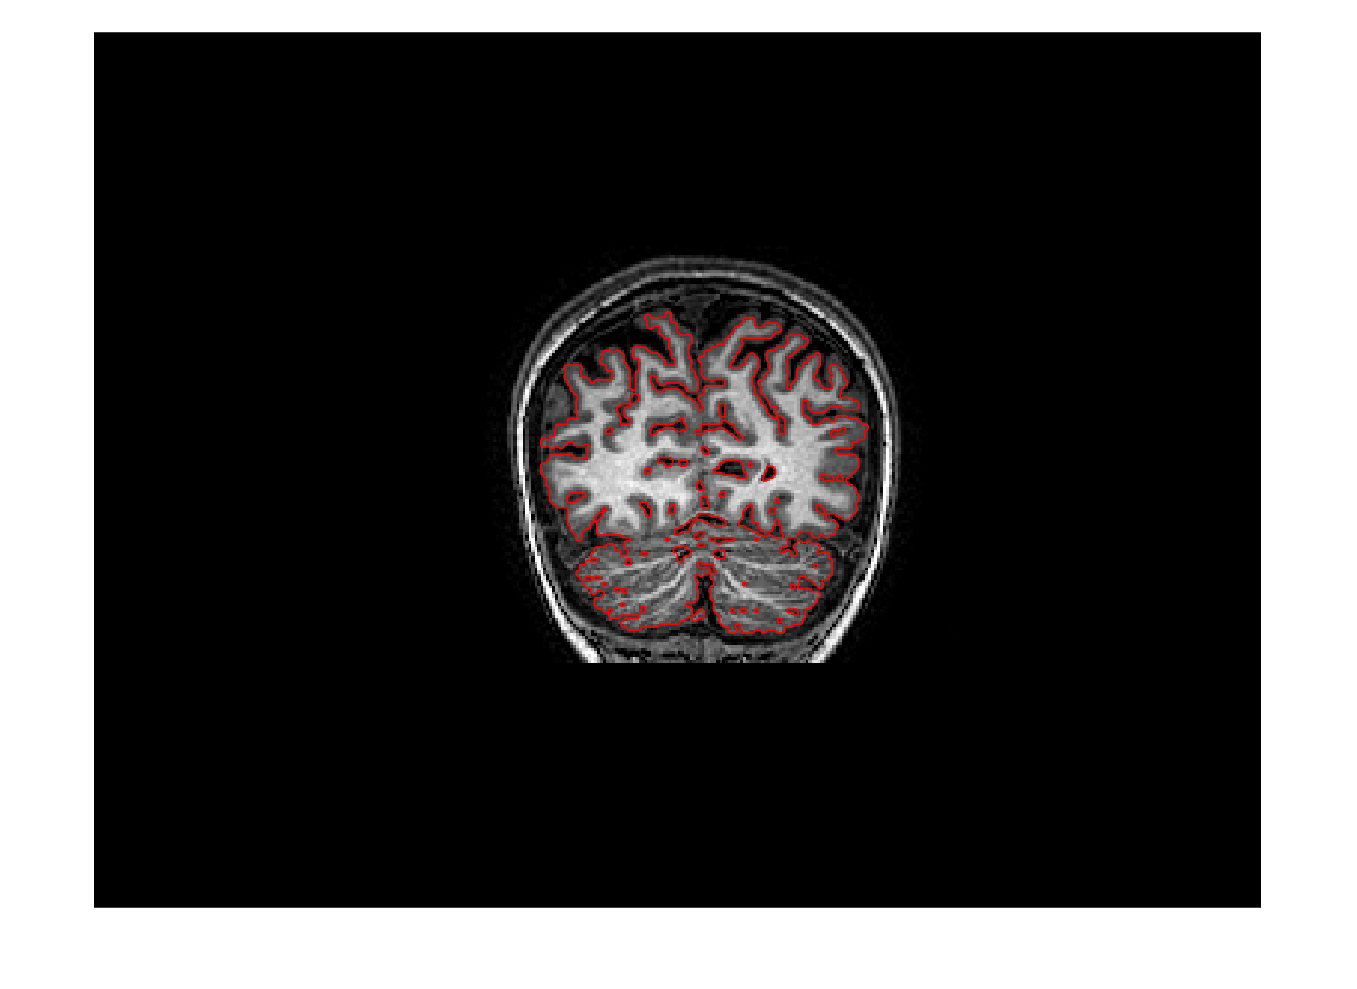


% Compute the number of voxels for each label
NofVoxels = zeros(N,1);
for ij=1:N
    
   NofVoxels(ij) = length(find(L==ij));
end

% Find the maximum component
[~,max_component] = max(NofVoxels);
BrainSegmentation = L == max_component;

figure
imshow(IM,[])
hold on
contour(BrainSegmentation > 0,'r')

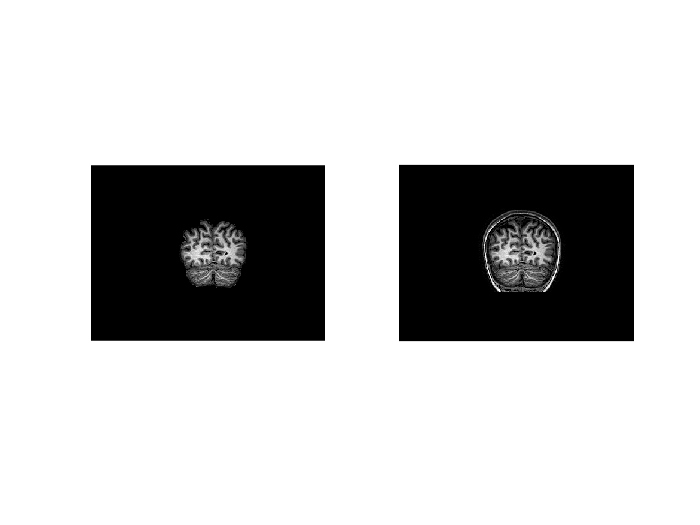


figure
sed = strel('square',30);
i_dilate = imdilate(BrainSegmentation,sed);
%imshow(i_dilate,[])
IM_f = IM-imcomplement(i_dilate);
%IM_f(IM_f>0.95)=0;
subplot(1,2,1)
imshow(IM_f)
subplot(1,2,2)
imshow(IM)